    clear all;
    close all;
%     randn('seed',100)
[X,y]=data(100,1.5)

X =     1.1585    1.0852   -0.7069   -1.2363   -1.4140   -1.2794    0.9474   -0.9713    1.1133   -0.9474   -1.5867   -1.3521   -1.2257    1.3450   -0.7414    0.9966    1.0585   -0.4972   -1.0695   -1.3959   -1.1542   -1.1573   -1.1370    0.6119   -0.9039   -1.2016    1.1554   -0.7604    0.6083    1.0966   -0.8041    0.7502    0.8032    1.3745   -0.8390   -1.5275   -1.2593   -0.9045    0.6326    1.1928   -0.8270   -1.2093   -1.1397    0.8838   -0.9124   -1.0841   -0.8416   -1.0181    0.8305   -0.7376
    1.0852   -0.7069   -1.2363   -1.4140   -1.2794    0.9474   -0.9713    1.1133   -0.9474   -1.5867   -1.3521   -1.2257    1.3450   -0.7414    0.9966    1.0585   -0.4972   -1.0695   -1.3959   -1.1542   -1.1573   -1.1370    0.6119   -0.9039   -1.2016    1.1554   -0.7604    0.6083    1.0966   -0.8041    0.7502    0.8032    1.3745   -0.8390   -1.5275   -1.2593   -0.9045    0.6326    1.1928   -0.8270   -1.2093   -1.1397    0.8838   -0.9124   -1.0841   -0.8416   -1.0181    0.8305   -0.7376    0

y =      1    -1    -1    -1    -1     1    -1     1    -1    -1    -1    -1     1    -1     1     1    -1    -1    -1    -1    -1    -1     1    -1    -1     1    -1     1     1    -1     1     1     1    -1    -1    -1    -1     1     1    -1    -1    -1     1    -1    -1    -1    -1     1    -1     1


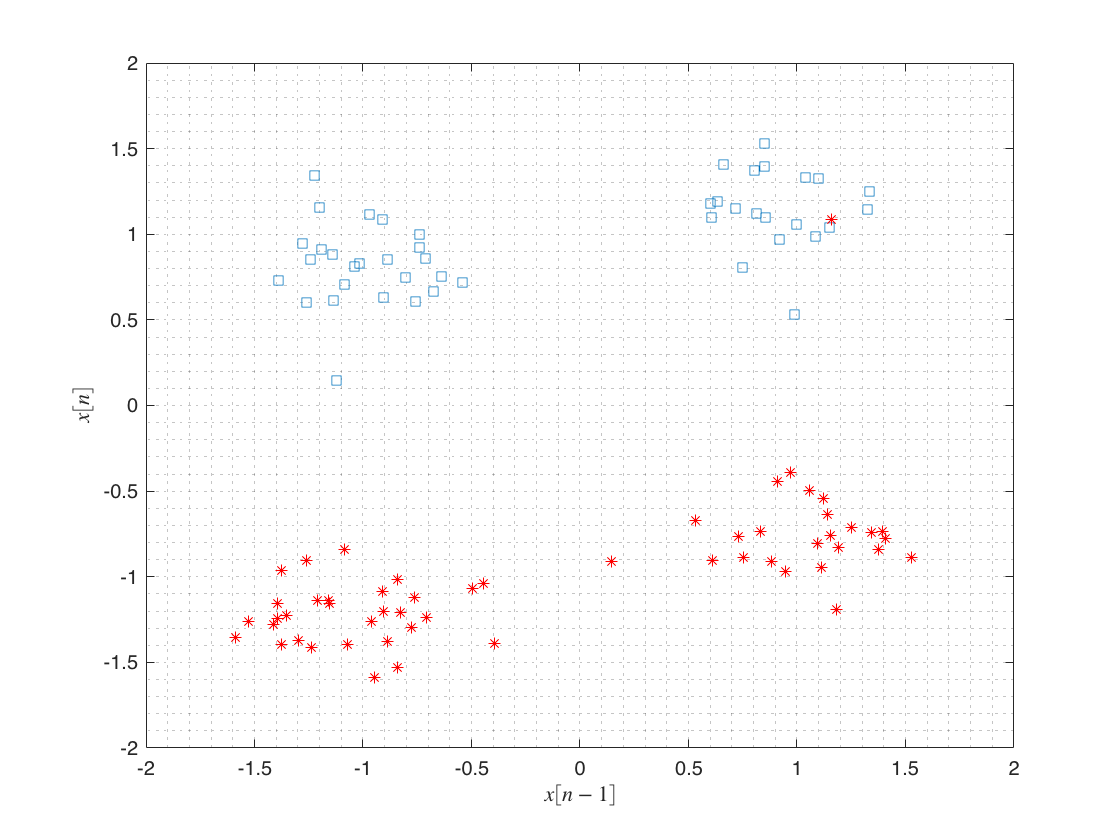


    x_center = 0;
    y_center = 0;
    center = transpose(repmat([x_center; y_center], 1, length(X)));

    theta = pi/2; % Rotate matrix 90° counter-clockwise
    v = X(:,1:2);

    R = [cos(theta) -sin(theta); sin(theta) cos(theta)];
    so = R*v';  % Rotate about the origin
    vo = so';

    X(:,1) = vo(:,1);
    X(:,2) = vo(:,2);

    
i1=find(y==1);
i2=find(y==-1);
figure(1)
plot(X(1,i1),X(2,i1),'s')
hold on
plot(X(1,i2),X(2,i2),'r*')
grid minor
xlabel('$x[n-1]$','Interpreter','latex')
ylabel('$x[n]$','Interpreter','latex')

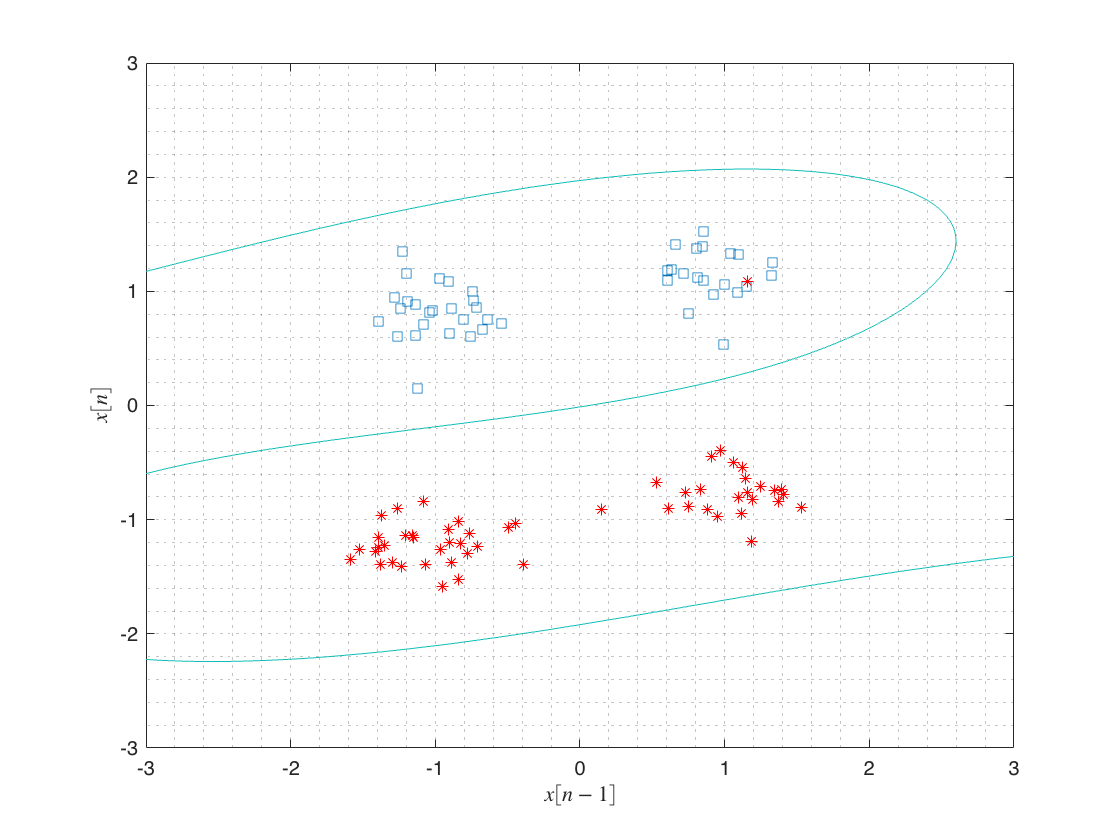

    % Train the datasets
    x_2 = X(1,:);
    x_3 = X(2,:);

    % Non-Linear Transformation (3rd Order)
    Volterra_eqn_train = [ones(1,100);x_2;x_3;x_2.^2;x_3.^2;x_2.*x_3;(x_2.^2).*x_3;(x_3.^2).*x_2;x_2.^3;x_3.^3];
    pi = Volterra_eqn_train * Volterra_eqn_train';
    w = pinv(pi) * Volterra_eqn_train * y';
    y = w' * Volterra_eqn_train;

    % Test the datasets
    % Grid/Xn_2 and Xn_3 Vectors
    [Xn_2,Xn_3] = meshgrid(linspace(-3,3,100), linspace(-3,3,100));    
    x_2 = Xn_2(:)';
    x_3 = Xn_3(:)';

    %3rd Order/Tranformation
    volterra_eqn_test = [ones(1,100.^2);x_2;x_3;x_2.^2;x_3.^2;x_2.*x_3;(x_2.^2).*x_3;(x_3.^2).*x_2;x_2.^3;x_3.^3];
    y_n = w' * volterra_eqn_test;

    % Buffering Vector into Matrix
    b = buffer(y_n,size(Xn_2,1),0);

    % Contour Plot for Matrix
    contour(Xn_2,Xn_3,b,[0 0])

function [X,y]=data(N,a)
N=N+1;
y=sign(randn(1,N));
x=filter([1 a],1,y)+0.2*randn(size(y));
X=buffer(x,2,1,'nodelay');  % Convolution
y=y(2:end);
end